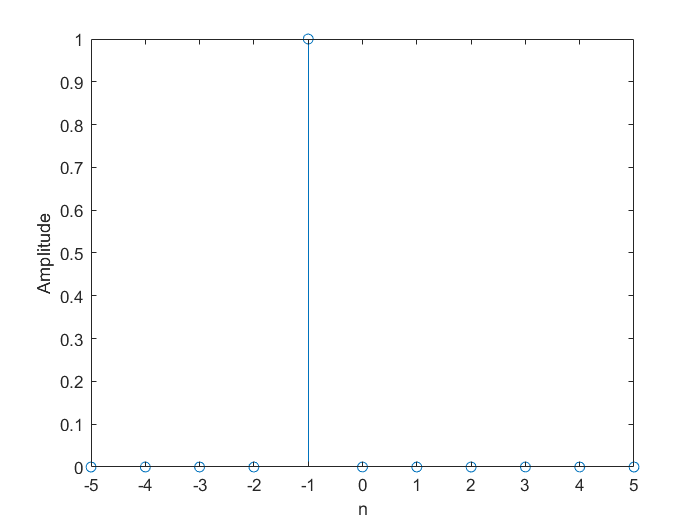

%%Unit impulse function
[n,a] = unitImpulse(-1,-5,5);
stem(n,a);

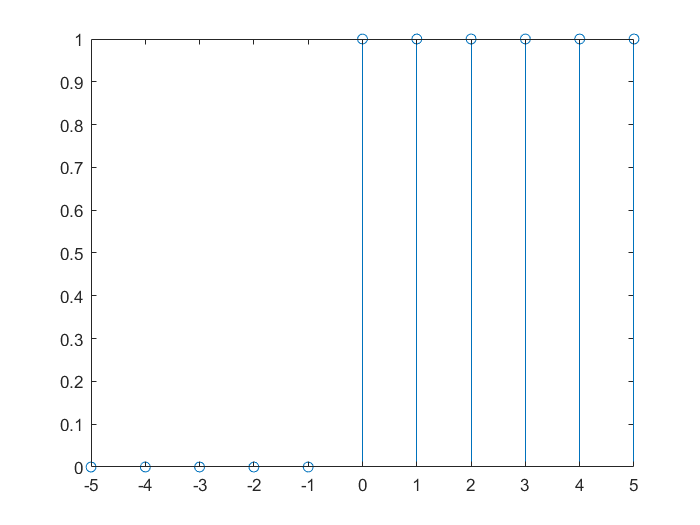

[n,a] = unitStep(0,-5,5);
stem(n,a);

`Local Function definitions`

function [n,amplitude] = unitImpulse(n0, n1, n2)
    n = n1:n2;
    %convert logical array into a double array
    amplitude = double((n-n0)==0);
    
end

function [n,amplitude] = unitStep(n0, n1, n2)
    n = n1:n2;
    %convert logical array into a double array
    amplitude = double(n>=n0);    
end